Зубчатое колесо установлено на вал диаметром d=40 мм с помощью соединения с натягом. При работе на колесо действуют тангенциальная Ft=2500 Н и осевая Fz=900 силы.

Рассчитать из условия отсутствия сдвига минимальный натяг, с которым колесо необходимо надеть на вал.

Ширина колеса l=40 мм, делительный диаметр колеса d2 = 120 мм. Материал вала и колеса - сталь (E=210000 МПа, *μ*=0,3).

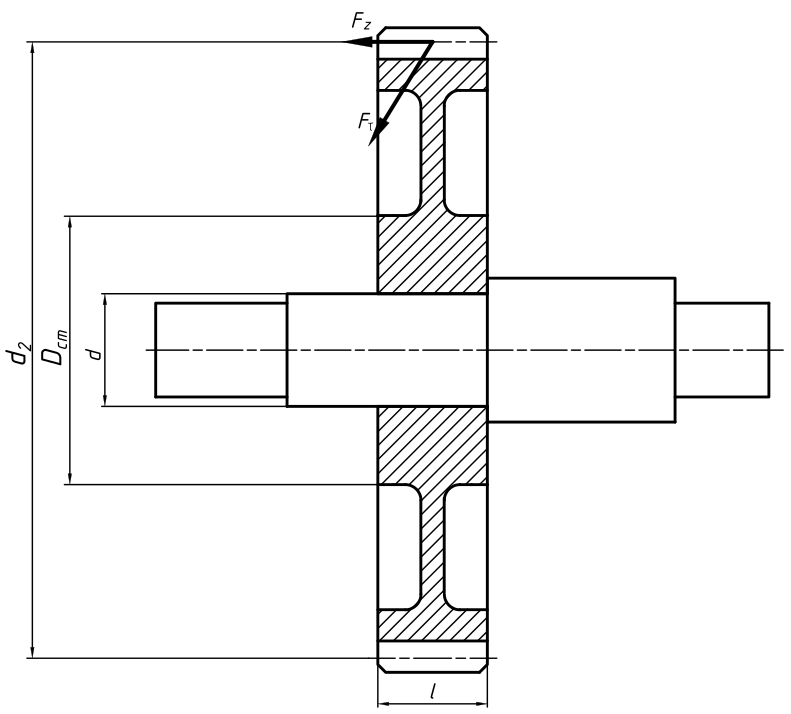

Для решения необходимо определить переменные, заданные в шаблоне (c1, c2, p, N)

d = 40;
l = 40;
d2 = 120;
Dst = 60;
Ft = 2500;
Fz = 900;
f = 0.12;
E1 = 2.1e5;
E2 = 2.1e5;
mu1 = 0.3;
mu2 = 0.3;

c1 = 0.7

c1 = 0.7000

c2 = (1 + (d/Dst)^2)/(1 - (d/Dst)^2) + mu2

c2 = 2.9000

T = Ft*d2/2000

T = 150


p = (((2000*T/d)^2 + Fz^2)^0.5)/(f*pi*d*l)

p = 12.5232


N = p*1000*d*(c1/E1+c2/E2)

N = 8.5873

Стальной двутавр длиной L = 500 мм приварен к стенке двумя угловыми швами сверху и снизу. На двутавр действует сила F=4 000 Н. Размеры двутавра h=50 мм, b=12 мм. Рассчитать катет сварного шва при условии, что допустимое напряжение $\left\lbrack \tau \right\rbrack =100\mathrm{МПа}$.

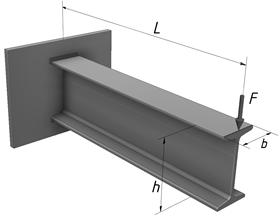

L = 500;
F = 400;
h = 50;
b = 12;
t_lim = 100;

k = (((F*L/h)^2 + (F/2)^2)^0.5)/(0.7*b*t_lim)

k = 4.7679

Шпилька с номинальным диаметром 12 мм ввёрнута в абсолютно жесткое основание. На неё с зазором надета втулка и притянута гайкой. Внутренний диаметр втулки – 12,5 мм, наружный – 23 мм Усилие затяжки в шпильке равно 8000 Н. Втулка и шпилька изготовлены из стали одной марки. Определите максимальное значение силы F, при котором втулка ещё будет оказывать давление на основание.

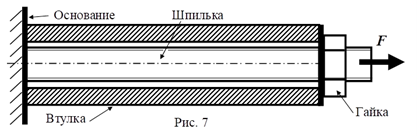

Ft = 8000;
d = 12;
P = 1.75;
d3 = d - 1.227*P;
d_in = 12.5;
D_ou = 23;

A_bolt = pi*d3^2/4

A_bolt = 76.2438

A_bush = 0.25*pi*(D_ou^2 - d_in^2)

A_bush = 292.7572


chi = 1/A_bush/(1/A_bolt+1/A_bush)

chi = 0.2066

F = Ft/(1-chi)

F = 1.0083e+04

Кронштейн служит для удержания подвесного груза на стене, устанавливается на четыре винта. К нему подвершен груз массой m=300 кг. Найти необходимую силу затяжки винтов по условию нераскрытия стыка, приняв что кронштейн стальной, а стена бетонная. Коэффициен основной нагрузки принять равным 0,7. Размеры l=500 мм, w=200 мм, b=160 мм, h=400 мм, a=360 мм.

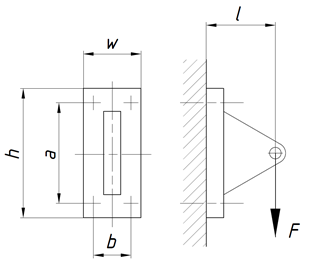

m = 300;
g = 9.81;
chi = 0.7;
l = 500;
w = 200;
b = 160;
h = 400;
a = 360;
k = 2;

W = w*h^2/6

W = 5.3333e+06


sig_T = (1-chi)*F*l/W

sig_T = 0.2836


sig_tight = sig_T*k

sig_tight = 0.5672


F_tight = sig_tight*w*h/4

F_tight = 1.1344e+04


F_tight2 = (1-chi)*F*l/(2*a)

F_tight2 = 2.1007e+03